% Name: Redwan-Ul-Bari
% ID: 190021119
% Section: A
% Part 2: Solving ODEs using RK4

###  Generator Parameters

A = mod((119*263+71),1000) + 1359

A = 1360

Y= sum(num2str(A)-'0')

Y = 10


Vf=220

Vf = 220

Rf= 150

Rf = 150

Lf= Y

Lf = 10

La= 0.1

La = 0.1000

Ra= 1.5

Ra = 1.5000

Rl=Y

Rl = 10

#### OEDs

syms t I_f Ia
Eg(I_f)=A3(1,1)+A3(2,1)*I_f+A3(3,1)*(I_f^2)+A3(4,1)*(I_f^3)+A3(5,1)*(I_f^4)

$$Eg(I\_f) = \frac{801727228581\,{I_{f}}^{4}}{4294967296}-\frac{704692782263\,{I_{f}}^{3}}{1073741824}+\frac{704493941181\,{I_{f}}^{2}}{1073741824}-\frac{3721168753\,I_{f}}{1073741824}+\frac{501079517853}{17179869184}$$

f1(t,I_f,Ia)= Vf/Lf -(Rf*I_f)/Lf

$$f1(t, I\_f, Ia) = 22-15\,I_{f}$$

f2(t,I_f,Ia)= Eg/La - (Ra*Ia)/La - (Ia*Rl)/La 

$$f2(t, I\_f, Ia) = \frac{4008636142905\,{I_{f}}^{4}}{2147483648}-\frac{3523463911315\,{I_{f}}^{3}}{536870912}+\frac{3522469705905\,{I_{f}}^{2}}{536870912}-\frac{18605843765\,I_{f}}{536870912}-115\,\mathrm{Ia}+\frac{2505397589265}{8589934592}$$

#### Solve using RK4

format long
h=0.01

h =    0.010000000000000


I_f=0

I_f =      0


Ia=double(Eg(0))/(Ra+Rl)

Ia =    2.536231883988797


i=1;
ea1=0;
ea2=0;

for t=0:h:1.3
    
k1_1=double(f1(t,I_f,Ia));

k1_2=double(f2(t,I_f,Ia));

k2_1=double(f1(t+h/2,I_f+k1_1*(h/2),Ia+k1_2*(h/2)));

k2_2=double(f2(t+h/2,I_f+k1_1*(h/2),Ia+k1_2*(h/2)));

k3_1=double(f1(t+h/2,I_f+k2_1*(h/2),Ia+k2_2*(h/2)));

k3_2=double(f2(t+h/2,I_f+k2_1*(h/2),Ia+k2_2*(h/2)));

k4_1=double(f1(t+h,I_f+k3_1*h,Ia+k3_2*h));

k4_2=double(f2(t+h,I_f+k3_1*h,Ia+k3_2*h));

I_f_n=I_f+(k1_1+2*k2_1+2*k3_1+k4_1)*(h/6);

Ian=Ia+(k1_2+2*k2_2+2*k3_2+k4_2)*(h/6);

ea1=((I_f_n-I_f)/I_f_n)*100;
ea2=((Ian-Ia)/Ian)*100;

T{i}=table(t,I_f,Ia,ea1,ea2,'VariableNames',{'Time (sec)','Field Current(if) (A)','Armature Circuit (Ia) A','% for If','% for Ia'});

I_f=I_f_n;
Ia=Ian;

i=i+1;

end

d=vertcat(T{:})

d = 131×5 table
    Time (sec)    Field Current(if) (A)    Armature Circuit (Ia) A        % for If            % for Ia     
    __________    _____________________    _______________________    ________________    _________________

          0                         0          2.5362318839888                     100     19.3604314287519
       0.01              0.2042940625         3.14514565110544        46.2570332958672     41.9778627878423
       0.02          0.38013171774585         5.42059600391007        28.4763153943006     36.2247620987863
       0.03         0.531476698720802         8.49953082465399        19.6850428898812     26.0171656439747
       0.04         0.661740624466874         11.4885174360203        14.4883175427567     17.6906452303127
       0.05          0.77385990481213          13.9577299

#### Polting growth of field current and armature current

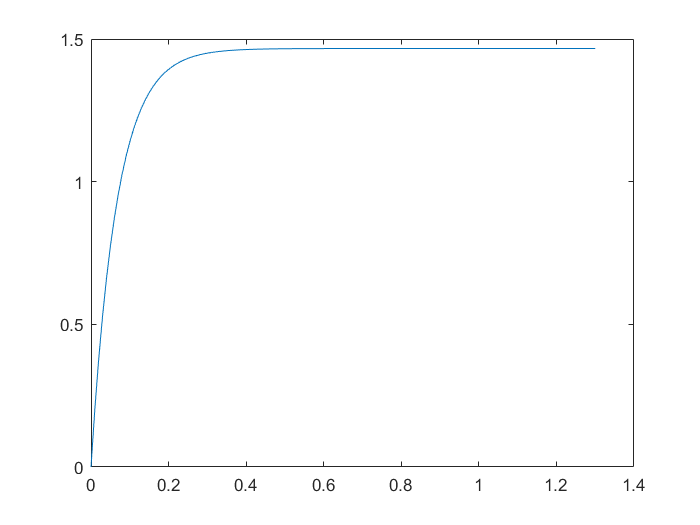

plot(table2array(d(:,1)),table2array(d(:,2)))

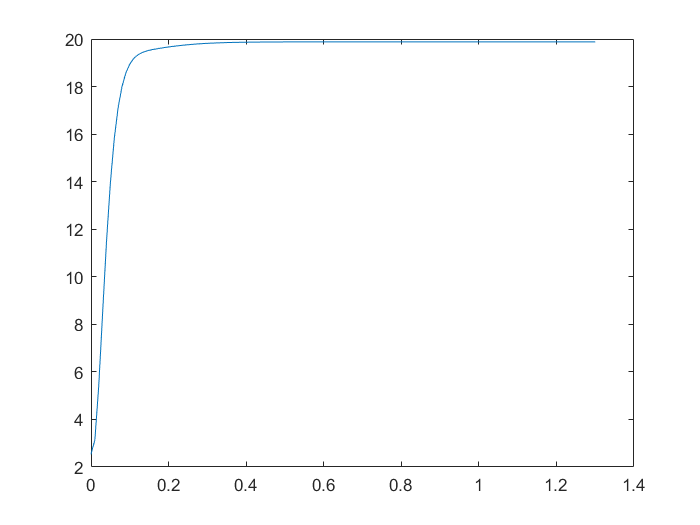

plot(table2array(d(:,1)),table2array(d(:,3)))